# **ELEC 4700 Assignment 4**

# **Circuit Modelling**

**Jay Maini 101037537**

**April 11th, 2021**

# Parts 1,2, and 3 

We can determine the value of resistance to be used in our circuit simulation by running a voltage sweep of our simulation code from the previous assignment and observing the current output. From the slope of the voltage versus current characteristic, we can derive the desired resistance using ohm's law, V/I, and applying a linear fit to the slope of this plot.

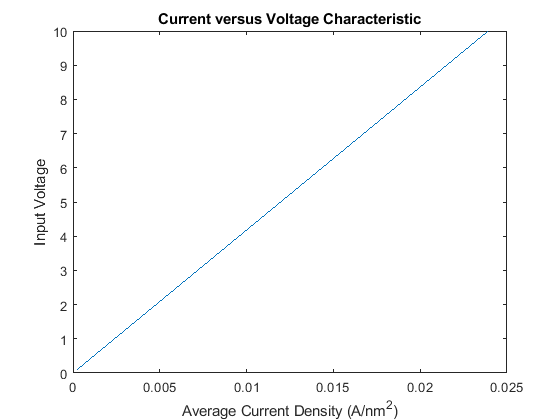

% Jay Maini 101037537
clear all
close all
set(0, 'DefaultFigureWindowStyle', 'docked')

%po = linspace(0.05, 0.95, 19);
v0 = linspace(0.1,10,20);
figure
for i=1:length(v0)
    Cur(i) = CurrentFinder(v0(i),0.5);
end
plot(Cur, v0)
hold on
ylabel('Input Voltage')
xlabel('Average Current Density (A/nm^2)')
title('Current versus Voltage Characteristic')

P = polyfit(Cur, v0, 1)

P =   418.1171   -0.0000


With a resistance value of R3 = 418 obtained, we can begin to implement our matrix with the same equations as from the circuit modelling PA simulation:


$$\begin{array}{l}
{\left.1\right)\;V_1 =V_{\mathrm{in}\;} \;} \\
{\left.2\right)\;G}_{1\;} \left(V_{2\;} -V_{1\;} \right)+C\frac{d\left(V_{2\;} -V_1 \right)\;}{\mathrm{dt}}+G_2 V_2 -I_L =0\\
{\left.3\right)\;V}_{2\;\;} -V_3 -L\frac{{\mathrm{dI}}_L \;}{\mathrm{dt}}=0\\
\left.4\right)\;-I_L +G_3 V_3 =0\\
{\left.5\right)\;V}_4 -{\mathrm{aI}}_3 =0\\
{\left.6\right)\;G}_3 V_3 -I_3 =0\\
{\left.7\right)\;G}_4 \left(V_o -V_4 \right)+G_o V_o =0
\end{array}$$


In the frequency domain, some of these equations can be rewritten as:


$$\begin{array}{l}
{\left.2\right)\;G}_{1\;} \left(V_{2\;} -V_{1\;} \right)+\mathrm{jwC}\left(V_2 -V_1 \right)+G_2 V_2 -I_L =0\\
{\left.3\right)\;V}_{2\;\;} -V_3 -{\mathrm{jwLI}}_L =0
\end{array}$$


In this form, we can model each of these elements in matrix form with a conductance matrix G, energy storage matrix C, and independent source vector F. 


$$G=\left\lbrack \begin{array}{ccccccc}
1 & 0 & 0 & 0 & 0 & 0 & 0\\
-\mathrm{G2} & \mathrm{G1}+\mathrm{G2} & -1 & 0 & 0 & 0 & 0\\
0 & 1 & 0 & -1 & 0 & 0 & 0\\
0 & 0 & -1 & \mathrm{G3} & 0 & 0 & 0\\
0 & 0 & 0 & 0 & -a & 1 & 0\\
0 & 0 & 0 & \mathrm{G3} & -1 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & -\mathrm{G4} & \mathrm{G4}+G_O 
\end{array}\right\rbrack \;\;C=\left\lbrack \begin{array}{ccccccc}
0 & 0 & 0 & 0 & 0 & 0 & 0\\
-C & C & 0 & 0 & 0 & 0 & 0\\
0 & 0 & -L & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack \;F=\left\lbrack \begin{array}{c}
V_{\mathrm{in}} \\
0\\
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack \;\;V=\left\lbrack \begin{array}{c}
V_1 \\
V_2 \\
I_L \\
V_3 \\
I_3 \\
V_4 \\
V_O 
\end{array}\right\rbrack$$



$$C\frac{\;\mathrm{dV}}{\mathrm{dt}}+\mathrm{GV}=F\;\to \left(G+\mathrm{jwC}\right)V=F\left(w\right)$$


The matrices are solved for the solution vector V and the output is shown on the following plots as a functio of gain at DC inputs and AC frequencies.

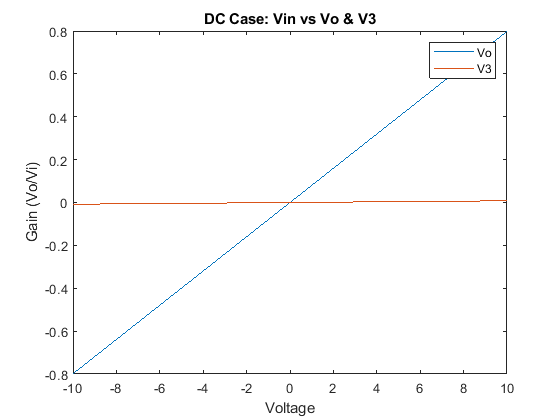

%Jay Maini 101037537
clear all
global G C F

%Circuit parameters
R1 = 1;
R2 = 2;
R3 = 418;
R4 = 0.1;
Ro = 1000;

L1 = 0.2;
a = 100;
C1 = 0.25;
G1 = 1/R1;
G2 = 1/R2;
G3 = 1/R3;
G4 = 1/R4;
Go = 1/Ro;

C = [0 0 0 0 0 0 0;
    -C1 C1 0 0 0 0 0;
    0 0 -L1 0 0 0 0;
    0 0 0 0 0 0 0;
    0 0 0 0 0 0 0;
    0 0 0 0 0 0 0;
    0 0 0 0 0 0 0];

G = [1 0 0 0 0 0 0;
    -G2 G1+G2 -1 0 0 0 0;
    0 1 0 -1 0 0 0;
    0 0 -1 G3 0 0 0;
    0 0 0 0 -a 1 0;
    0 0 0 G3 -1 0 0;
    0 0 0 0 0 -G4 G4+Go];

F = [1;0;0;0;0;0;0];

%[V1 V2 IL V3 I3 V4 Vo]

%DC Case

s = 0; %no capacitive/inductive effects
Vin = linspace(-10, 10, 100);
V3 = zeros(size(Vin));
Vo = zeros(size(Vin));
for i=1:length(Vin)
   V = (G+s.*C)\(F.*Vin(i)); 
   V3(i) = V(4)*G3;
   Vo(i) = V(7);
end


figure
%subplot(2,3,1)
plot(Vin,Vo)
hold on
plot(Vin,V3)
title('DC Case: Vin vs Vo & V3')
xlabel('Voltage')
ylabel('Gain (Vo/Vi)')
legend('Vo','V3')

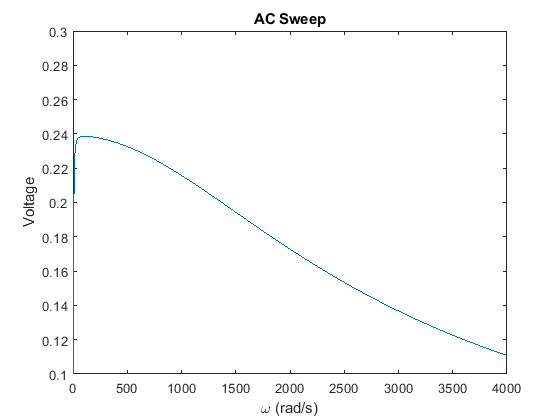


f = linspace(0.01, 1000, 10000);
w = 2*pi*f;
Vo = zeros(size(f));
for i = 1:length(f)
    s = j*w(i);
    V = (G+s*C)\F;  % Solving
    Vo(i) = V(7);
end
%subplot(2,3,2)
figure
plot(w,abs(Vo));
title('AC Sweep');
xlabel('\omega (rad/s)');
ylabel('Voltage');
ylim([0.1 0.3])
xlim([0 4000])

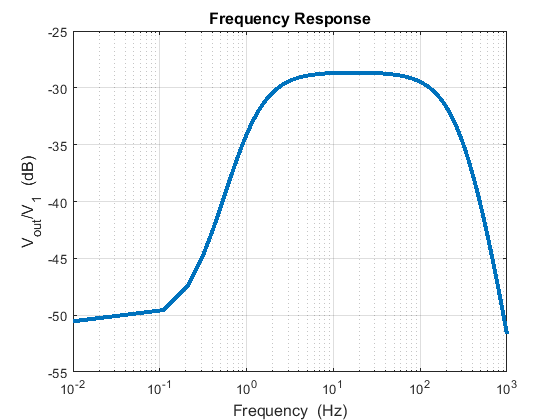


%subplot(2,3,3)
figure
semilogx(f, 20*log(abs(Vo)),'LineWidth',3);
grid;
title('Frequency Response', 'FontSize',12);
xlabel('Frequency  (Hz)','FontSize',12);
ylabel('V_{out}/V_{1}  (dB)','FontSize',12);

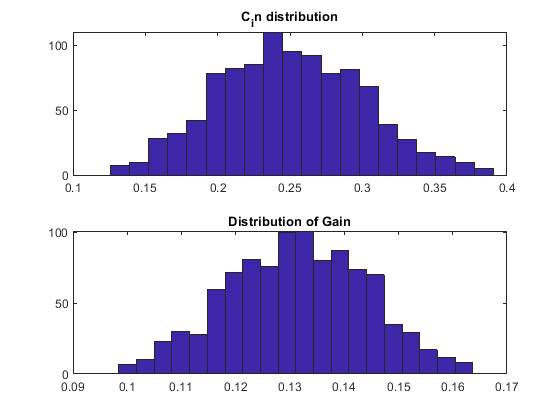


%subplot(2,3,4)
figure
subplot(2,1,1)
%normal distribution of Capacitance
C1_dist = C1 + 0.05 * randn(1000,1);
hist(C1_dist, 20)
title('C_in distribution')

%subplot(2,3,5)
subplot(2,1,2)
Vo = zeros(size(C1_dist));
s = 1i*pi;
%Solved distribution of gain 
for i = 1:length(C1_dist)
    C1 = C1_dist(i);
    %recalculate C matrix
    C = [0 0 0 0 0 0 0;
    -C1 C1 0 0 0 0 0;
    0 0 -L1 0 0 0 0;
    0 0 0 0 0 0 0;
    0 0 0 0 0 0 0;
    0 0 0 0 0 0 0;
    0 0 0 0 0 0 0];
    
    V = (G+s.*C)\(F);
    Vo(i) = abs(V(7));
end
hist(Vo, 20)
title('Distribution of Gain')

# Part 4 

The circuit can also be simulated in the time domain, contrasting with the frequency domain results shown above. This is possible using a formulation with the finite difference method by resolving a solution from previous iterations of the solution verctor over time.

For this circuit, which by inspection appears to be a type of amplifier, has a negative gain due to the resistance value of R3 selected - the default value of R3 = 10 yields substantial positive gain. Due to the frequency response as determined earlier, this amplifier is functioning as a low pass filter, allowing lower frequencies with only a reduced gain, while the magnitude substantially drops at frequencies beyond ~200 Hz.

To formulate in the time domain, we use the Backwards Euler method to write our solution vector in terms of the previous solution vector's iteration over time. Thus, we can re-arrange our solution to the following:


$$C\;\frac{\mathrm{dV}}{\mathrm{dt}}+\mathrm{GV}\left(t\right)=F\left(t\right)\to {\;\;V}^j =A^{-1} \left\lbrack C\;\frac{V^{j-1} }{\Delta t}+F\left(t^{\left.j\right)} \right)\right\rbrack ,\mathrm{where}\;A=\frac{C}{\Delta t}+G$$


For this simulation in the time domain, three different voltage inputs are shown below. A step input that transitions at 30ms, a sinusoid input at two different frequencies, and a gaussian pulse input. Each of these show the negative gain as observed in the AC analysis in part 1.

Note that for the sinusoid input, decreasing the frequency narrows the two band pass regions to become closer together. A higher frequency has the opposite effect in increasing the frequency composition.

When the time step is increased, say from 1ms to 2ms, the content of the graphs remains the same - however, the x axis on the fourier transform changes its scale to center the frequency regions at exactly half of the max time iteration of 1 second. In these plots, this can be observed as 500ms, shown as 500 on the x axes.

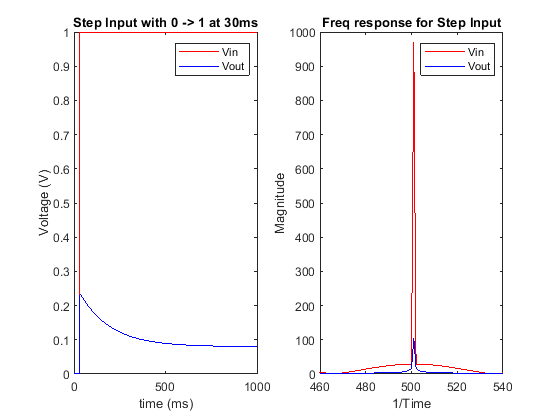

%Jay Maini 101037537
clear all
global G C F

%Circuit parameters
R1 = 1;
R2 = 2;
R3 = 418;
R4 = 0.1;
Ro = 1000;

L1 = 0.2;
a = 100;
C1 = 0.25;
G1 = 1/R1;
G2 = 1/R2;
G3 = 1/R3;
G4 = 1/R4;
Go = 1/Ro;

C = [0 0 0 0 0 0 0;
    -C1 C1 0 0 0 0 0;
    0 0 -L1 0 0 0 0;
    0 0 0 0 0 0 0;
    0 0 0 0 0 0 0;
    0 0 0 0 0 0 0;
    0 0 0 0 0 0 0];

G = [1 0 0 0 0 0 0;
    -G2 G1+G2 -1 0 0 0 0;
    0 1 0 -1 0 0 0;
    0 0 -1 G3 0 0 0;
    0 0 0 0 -a 1 0;
    0 0 0 G3 -1 0 0;
    0 0 0 0 0 -G4 G4+Go];

F = [1;0;0;0;0;0;0];

%[V1 V2 IL V3 I3 V4 Vo]

%Initialize three input signals 
Vin = zeros(1,1000);
f = 1/30;
V = zeros(7,1);

figure
subplot(1,2,1)
%Step input -----------------------------------------------
for i=1:1000
   if (i >= 30)
    Vin(i) = 1;
   end
   
   A = C/0.001 + G;
   V_p = V;
   V = A\((C*V_p/0.001) + F*Vin(i));
  % Vout(i) = V(7);
   Vo(i) = V(7);
   
   if (i >= 2)
        plot([i i-1], [Vin(i) Vin(i-1)], 'r')
        hold on
        plot([i i-1], [Vo(i) Vo(i-1)], 'b')
        
   end
    
end
title('Step Input with 0 -> 1 at 30ms')
xlabel('time (ms)')
ylabel('Voltage (V)')
legend('Vin','Vout')

subplot(1,2,2)
shrek = fftshift(fft(Vin));
plot(abs(shrek), 'r')

hold on
shrek2 = fftshift(fft(Vo));
plot(abs(shrek2), 'b')
xlim([460 540])

title('Freq response for Step Input')
xlabel('1/Time')
ylabel('Magnitude')
legend('Vin','Vout')

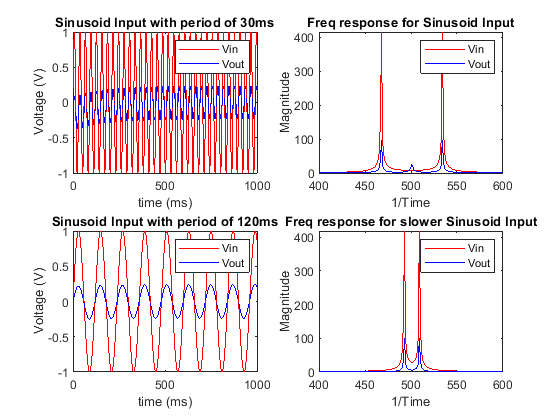


%Sinusodal input -------------------------------------
figure
subplot(2,2,1)
for i=1:1000
    Vin(i) = sin(2*pi*f*i);
    
   A = C/0.001 + G;
   V_p = V;
   V = A\((C*V_p/0.001) + F*Vin(i));
   Vo(i) = V(7);
   
   if (i >= 2)
        plot([i i-1], [Vin(i) Vin(i-1)], 'r')
        hold on
        plot([i i-1], [Vo(i) Vo(i-1)], 'b')
   end
    
end
title('Sinusoid Input with period of 30ms')
xlabel('time (ms)')
ylabel('Voltage (V)')
legend('Vin','Vout')

subplot(2,2,2)
shrek = fftshift(fft(Vin));
plot(abs(shrek), 'r')

hold on
shrek2 = fftshift(fft(Vo));
plot(abs(shrek2), 'b')
xlim([400 600])

title('Freq response for Sinusoid Input')
xlabel('1/Time')
ylabel('Magnitude')
legend('Vin','Vout')

%Sinusodal input - 2nd frequency -------------------------
subplot(2,2,3)
f = 1/120;
for i=1:1000
    Vin(i) = sin(2*pi*f*i);
    
   A = C/0.001 + G;
   V_p = V;
   V = A\((C*V_p/0.001) + F*Vin(i));
   Vo(i) = V(7);
   
   if (i >= 2)
        plot([i i-1], [Vin(i) Vin(i-1)], 'r')
        hold on
        plot([i i-1], [Vo(i) Vo(i-1)], 'b')
   end
    
end
title('Sinusoid Input with period of 120ms')
xlabel('time (ms)')
ylabel('Voltage (V)')
legend('Vin','Vout')

subplot(2,2,4)
shrek = fftshift(fft(Vin));
plot(abs(shrek), 'r')

hold on
shrek2 = fftshift(fft(Vo));
plot(abs(shrek2), 'b')
xlim([400 600])

title('Freq response for slower Sinusoid Input')
xlabel('1/Time')
ylabel('Magnitude')
legend('Vin','Vout')

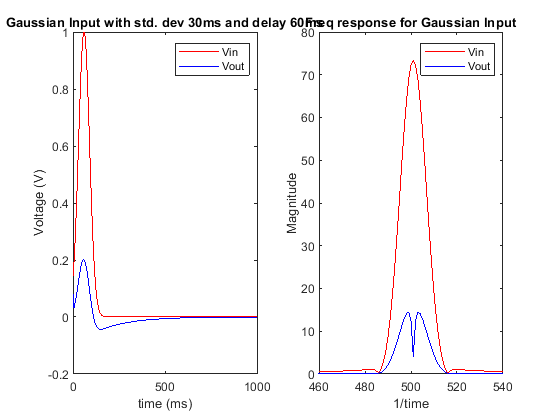


%Gaussian Input ------------------------------------
figure
subplot(1,2,1)
for i=1:1000
    %gaussian parameters
    a = 1;
    b = 60;
    c = 30;
    Vin(i) = a*exp(-(i-b)^2/(2*c^2));

    A = C/0.001 + G;
   V_p = V;
   V = A\((C*V_p/0.001) + F*Vin(i));
   Vo(i) = V(7);

    if (i >= 2)
        plot([i i-1], [Vin(i) Vin(i-1)], 'r')
        hold on
        plot([i i-1], [Vo(i) Vo(i-1)], 'b')
    end
end
title('Gaussian Input with std. dev 30ms and delay 60ms')
xlabel('time (ms)')
ylabel('Voltage (V)')
legend('Vin','Vout')

subplot(1,2,2)
shrek = fftshift(fft(Vin));
plot(abs(shrek), 'r')

hold on
shrek2 = fftshift(fft(Vo));
plot(abs(shrek2), 'b')
xlim([460 540])

title('Freq response for Gaussian Input')
xlabel('1/time')
ylabel('Magnitude')
legend('Vin','Vout')

# Part 5

We can now simulate the same circuit with gaussian input with noise characteristics. This is done with the addition of an indepent current source, I_n, running in parallel with resistor R3. We then limit the bandwidth of the noise with a capacitor Cn, also in parallel.

The I_n random number function can simply be added in using the F vector, which handles all independent sources, into the solution vector for I3. The current added by the noise is then considered by the current value. The Cn capacitor will be added into the C matrix as an energy storage device, by modifying equations 4 and 6. 


$$\begin{array}{l}
\left.4\right)\;-I_L +G_3 V_3 +C_n \frac{d}{\mathrm{dt}}V_3 =0\\
{\left.6\right)\;G}_3 V_3 +C_n \frac{d}{\mathrm{dt}}V_3 -I_3 =0
\end{array}$$



$$\;\;C=\left\lbrack \begin{array}{ccccccc}
0 & 0 & 0 & 0 & 0 & 0 & 0\\
-C & C & 0 & 0 & 0 & 0 & 0\\
0 & 0 & -L & 0 & 0 & 0 & 0\\
0 & 0 & 0 & C_n  & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & C_n  & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack \;F=\left\lbrack \begin{array}{c}
V_{\mathrm{in}} \\
0\\
0\\
0\\
I_n \\
0\\
0
\end{array}\right\rbrack \;\;V=\left\lbrack \begin{array}{c}
V_1 \\
V_2 \\
I_L \\
V_3 \\
I_3 \\
V_4 \\
V_O 
\end{array}\right\rbrack$$


Note that for the following plots, a noise current magnitude of 0.01 instead of 0.001 is used due to the negative gain of the circuit. At a magnitude of 0.001, the noise is still visible, but much harder to depict visually and does not appear on the fourier transform plot at the current time step.

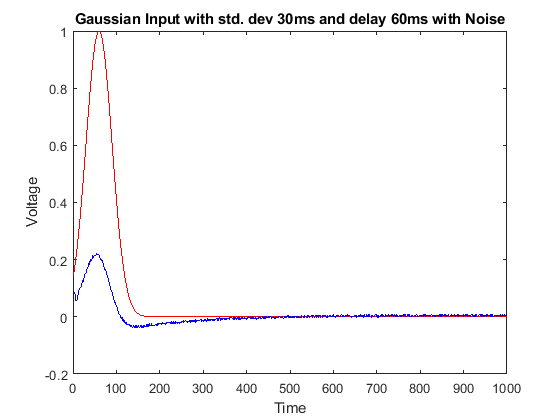

%Jay Maini 101037537
clear all
global G C F

%Circuit parameters
R1 = 1;
R2 = 2;
R3 = 418;
R4 = 0.1;
Ro = 1000;

L1 = 0.2;
a = 100;
C1 = 0.25;
G1 = 1/R1;
G2 = 1/R2;
G3 = 1/R3;
G4 = 1/R4;
Go = 1/Ro;

%Bandwidth limiting capacitor
Cn = 0.00001;
%Cn = 0;

C = [0 0 0 0 0 0 0;
    -C1 C1 0 0 0 0 0;
    0 0 -L1 0 0 0 0;
    0 0 0 Cn 0 0 0;
    0 0 0 0 0 0 0;
    0 0 0 Cn 0 0 0;
    0 0 0 0 0 0 0];

G = [1 0 0 0 0 0 0;
    -G2 G1+G2 -1 0 0 0 0;
    0 1 0 -1 0 0 0;
    0 0 -1 G3 0 0 0;
    0 0 0 0 -a 1 0;
    0 0 0 G3 -1 0 0;
    0 0 0 0 0 -G4 G4+Go];

F = [1;0;0;0;0;0;0];

%[V1 V2 IL V3 I3 V4 Vo]

%Time step
time = 1000;

%Initialize three input signals 
Vin = zeros(1,time);
f = 1/(0.03*time);

V = zeros(7,1);

In = 0.01*rand(time,1);
figure
%Gaussian Input
for i=1:time
    %gaussian parameters
    a = 1;
    b = 0.06*time;
    c = 0.03*time;
    Vin(i) = a*exp(-(i-b)^2/(2*c^2));
    
    %recalculate F vector
    F = [Vin(i);0;0;0;In(i);0;0];

    A = C/0.001 + G;
   V_p = V;
   V = A\((C*V_p/0.001) + F);
   Vo(i) = V(7);

    if (i >= 2)
        plot([i i-1], [Vin(i) Vin(i-1)], 'r')
        hold on
        plot([i i-1], [Vo(i) Vo(i-1)], 'b')
    end
end
title('Gaussian Input with std. dev 30ms and delay 60ms with Noise')
ylabel('Voltage')
xlabel('Time')

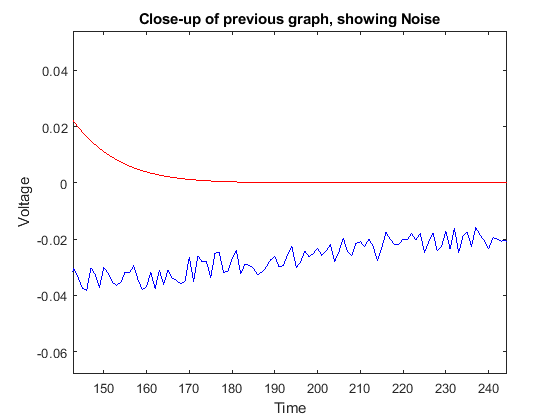


figure
%Gaussian Input - Zoomed in result
for i=1:time
    %gaussian parameters
    a = 1;
    b = 0.06*time;
    c = 0.03*time;
    Vin(i) = a*exp(-(i-b)^2/(2*c^2));
    
    %recalculate F vector
    F = [Vin(i);0;0;0;In(i);0;0];

    A = C/0.001 + G;
   V_p = V;
   V = A\((C*V_p/0.001) + F);
   Vo(i) = V(7);

    if (i >= 2)
        plot([i i-1], [Vin(i) Vin(i-1)], 'r')
        hold on
        plot([i i-1], [Vo(i) Vo(i-1)], 'b')
    end
end
title('Close-up of previous graph, showing Noise')
ylabel('Voltage')
xlabel('Time')

xlim([142.8 244.3])
ylim([-0.068 0.054])

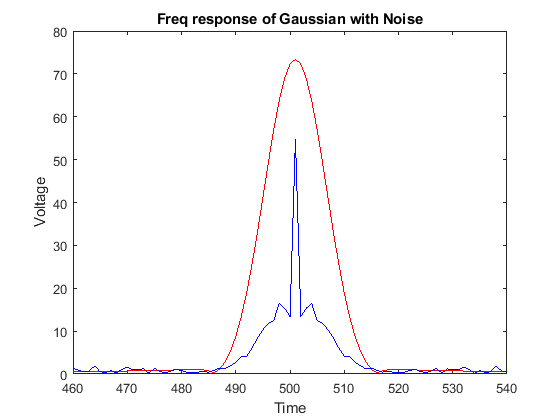


%Gaussian with noise - FFT plot
In = 0.1*rand(time,1);
for i=1:time
    %gaussian parameters
    a = 1;
    b = 0.06*time;
    c = 0.03*time;
    Vin(i) = a*exp(-(i-b)^2/(2*c^2));
    
    %recalculate F vector
    F = [Vin(i);0;0;0;In(i);0;0];

    A = C/0.001 + G;
   V_p = V;
   V = A\((C*V_p/0.001) + F);
   Vo(i) = V(7);

end

figure
shrek = fftshift(fft(Vin));
plot(abs(shrek), 'r')

hold on
shrek2 = fftshift(fft(Vo));
plot(abs(shrek2), 'b')
xlim([460 540])
title('Freq response of Gaussian with Noise')
ylabel('Voltage')
xlabel('Time')

We can vary the value of the limiting Capacitor Cn and observe the effect it has on the output waveform. A large Cn value allows a bandwidth of higher frequencies to propagate, creating instability in the output signal, shown below. A small Cn signal creates a more steady-state value and removes much of the oscillation, resulting in a lower bandwidth.

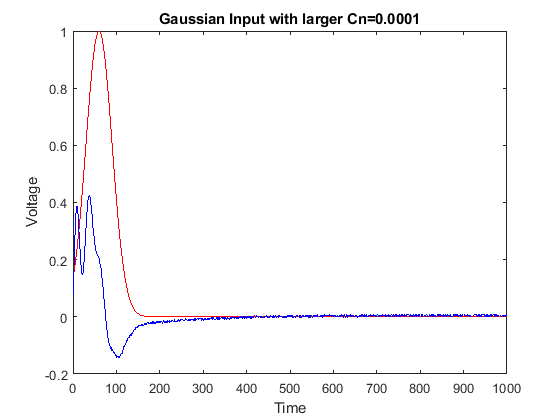

%recalculate Cn with different values
In = 0.01*rand(time,1);
Cn = 0.0001;

C = [0 0 0 0 0 0 0;
    -C1 C1 0 0 0 0 0;
    0 0 -L1 0 0 0 0;
    0 0 0 Cn 0 0 0;
    0 0 0 0 0 0 0;
    0 0 0 Cn 0 0 0;
    0 0 0 0 0 0 0];

figure
%Gaussian Input - Zoomed in result, Cn LARGE ------------------
for i=1:time
    %gaussian parameters
    a = 1;
    b = 0.06*time;
    c = 0.03*time;
    Vin(i) = a*exp(-(i-b)^2/(2*c^2));
    
    %recalculate F vector
    F = [Vin(i);0;0;0;In(i);0;0];

    A = C/0.001 + G;
   V_p = V;
   V = A\((C*V_p/0.001) + F);
   Vo(i) = V(7);

    if (i >= 2)
        plot([i i-1], [Vin(i) Vin(i-1)], 'r')
        hold on
        plot([i i-1], [Vo(i) Vo(i-1)], 'b')
    end
end
title('Gaussian Input with larger Cn=0.0001')
ylabel('Voltage')
xlabel('Time')

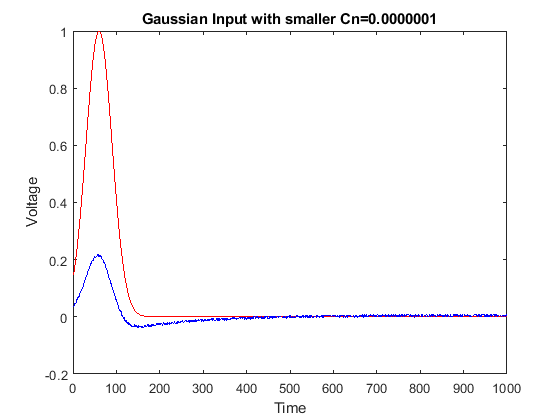


Cn = 0.0000001;

C = [0 0 0 0 0 0 0;
    -C1 C1 0 0 0 0 0;
    0 0 -L1 0 0 0 0;
    0 0 0 Cn 0 0 0;
    0 0 0 0 0 0 0;
    0 0 0 Cn 0 0 0;
    0 0 0 0 0 0 0];

figure
%Gaussian Input - Zoomed in result, Cn SMALL ------------------
for i=1:time
    %gaussian parameters
    a = 1;
    b = 0.06*time;
    c = 0.03*time;
    Vin(i) = a*exp(-(i-b)^2/(2*c^2));
    
    %recalculate F vector
    F = [Vin(i);0;0;0;In(i);0;0];

    A = C/0.001 + G;
   V_p = V;
   V = A\((C*V_p/0.001) + F);
   Vo(i) = V(7);

    if (i >= 2)
        plot([i i-1], [Vin(i) Vin(i-1)], 'r')
        hold on
        plot([i i-1], [Vo(i) Vo(i-1)], 'b')
    end
end
title('Gaussian Input with smaller Cn=0.0000001')
ylabel('Voltage')
xlabel('Time')

The time steps can also be adjusted and observe their effect on the output. A larger timestep allows slightly higher gain and reduces the "bounce-back" effect from the output compared to the shorter timestep, which reduces the output value but further dampens any second stage oscillation. The below figures illustrate this effect.

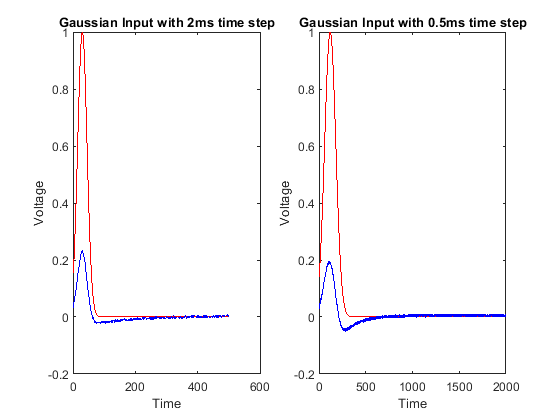

%Different TIME STEPS ------------------------------------------

%Time step
time = 500;

%Initialize three input signals 
Vin = zeros(1,time);
f = 1/(0.03*time);

V = zeros(7,1);

In = 0.01*rand(time,1);
figure
subplot(1,2,1)
%Gaussian Input
for i=1:time
    %gaussian parameters
    a = 1;
    b = 0.06*time;
    c = 0.03*time;
    Vin(i) = a*exp(-(i-b)^2/(2*c^2));
    
    %recalculate F vector
    F = [Vin(i);0;0;0;In(i);0;0];

    A = C/0.001 + G;
   V_p = V;
   V = A\((C*V_p/0.001) + F);
   Vo(i) = V(7);

    if (i >= 2)
        plot([i i-1], [Vin(i) Vin(i-1)], 'r')
        hold on
        plot([i i-1], [Vo(i) Vo(i-1)], 'b')
    end
end
title('Gaussian Input with 2ms time step')
ylabel('Voltage')
xlabel('Time')


%Time step
time = 2000;

%Initialize three input signals 
Vin = zeros(1,time);
f = 1/(0.03*time);

V = zeros(7,1);

In = 0.01*rand(time,1);
%Gaussian Input
subplot(1,2,2)
for i=1:time
    %gaussian parameters
    a = 1;
    b = 0.06*time;
    c = 0.03*time;
    Vin(i) = a*exp(-(i-b)^2/(2*c^2));
    
    %recalculate F vector
    F = [Vin(i);0;0;0;In(i);0;0];

    A = C/0.001 + G;
   V_p = V;
   V = A\((C*V_p/0.001) + F);
   Vo(i) = V(7);

    if (i >= 2)
        plot([i i-1], [Vin(i) Vin(i-1)], 'r')
        hold on
        plot([i i-1], [Vo(i) Vo(i-1)], 'b')
    end
end
title('Gaussian Input with 0.5ms time step')
ylabel('Voltage')
xlabel('Time')

# Part 6

(The solution to this part of the assignment is an estimate at best, using the resources available. The procedure is incomplete).

To add non-linear characteristics to the circuit, an additional vector B(V) is used. The full solution then becomes:

 
$$C\;\frac{\mathrm{dV}}{\mathrm{dt}}+\mathrm{GV}\left(t\right)+B\left(V\right)=F\left(t\right)\to {\;\;V}^j =A^{-1} \left\lbrack C\;\frac{V^{j-1} }{\Delta t}+F\left(t^{\left.j\right)} \right)-B\left(V^j \right)\right\rbrack ,\;\;\mathrm{where}\;A=\frac{C}{\Delta t}+G$$


The non-linear effects apply solely to equation 5, which becomes rewritten as:

## 
$$V_4 -{\alpha I}_3 -\beta I_3^2 -\gamma I_{3 }^3 =0$$



$$G=\left\lbrack \begin{array}{ccccccc}
1 & 0 & 0 & 0 & 0 & 0 & 0\\
-\mathrm{G2} & \mathrm{G1}+\mathrm{G2} & -1 & 0 & 0 & 0 & 0\\
0 & 1 & 0 & -1 & 0 & 0 & 0\\
0 & 0 & -1 & \mathrm{G3} & 0 & 0 & 0\\
0 & 0 & 0 & 0 & -a & 1 & 0\\
0 & 0 & 0 & \mathrm{G3} & -1 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & -\mathrm{G4} & \mathrm{G4}+G_O 
\end{array}\right\rbrack \;\;V=\left\lbrack \begin{array}{c}
V_1 \\
V_2 \\
I_L \\
V_3 \\
I_3 \\
V_4 \\
V_O 
\end{array}\right\rbrack \;\;B=\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
-\beta^{\frac{1}{2}} -\gamma^{\frac{1}{3}} \\
0\\
0
\end{array}\right\rbrack$$


To solve this non-linear circuit, a frequency domain analysis must first be done to determine an operating point at t = 0.We use a Jacobian to linearize a non-linear solution at this point in time. We define the operating point as X_op and we would solve with the following:


$${\mathrm{GX}}_{\mathrm{op}} +B=F\left(0\right)$$



$$J=\frac{\mathrm{dB}}{\mathrm{dX}}$$


Once an operating point is achieved, all equations involving the frequency domain can be written in terms of a small signal expansion.

function J_avg = CurrentFinder(v0, percent_open)
    set(0, 'DefaultFigureWindowStyle','docked')

    %v0 = 1;
    %unequal array size
    nx = 200;
    ny = 100;
    V = zeros(nx,ny);
    G = sparse(nx*ny, nx*ny);
    F = zeros(nx*ny,1);

    %Easy adjustment for bottleneck size - useful for function
    %percent_open = 0.33;
    percent_boundary = (1 - percent_open)/2;
    b_height_1 = round(percent_boundary*ny);
    b_height_2 = round(ny-percent_boundary*ny);

    %Make conductivity array 
    cMap = zeros(nx,ny) + 1;
    %Create bottleneck areas
    BNx = [(2/5)*nx (3/5)*nx];
    %BNx = [b_height_1 b_height_2];
    BNy1 = [1 b_height_1];
    BNy2 = [b_height_2 ny];
    %Modify cMap values

    for o = BNx(1):BNx(2)
        for p = BNy1(1):BNy1(2)
            cMap(o,p) = 1e-2;
        end
        for u = BNy2(1):BNy2(2)
            cMap(o,u) = 1e-2;
        end
    end
    
    for i = 1:nx
        for j = 1:ny
            m = j+(i-1)*ny;
            %Edge cases (BC's nodes)
            if (i == 1)
                F(m) = v0;
                G(m,m) = 1;
            elseif (i == nx)
                F(m) = 0;
                G(m,m) = 1;
            elseif (j == 1)
                %Bottom side - only three resistors
                npy = j+1 + (i-1)*ny;
                npx = j + (i-1+1)*ny;
                nmx = j + (i-1-1)*ny;
                nmy = j-1 + (i-1)*ny;

                %Calculate resistances based on conductivity map
                rpx = (cMap(i,j) + cMap(i+1,j))/2;
                rmx = (cMap(i,j) + cMap(i-1,j))/2;
                rpy = (cMap(i,j) + cMap(i,j+1))/2;

                G(m,m) = -(rpx+rmx+rpy);
                G(m,npx) = rpx; 
                G(m,nmx) = rmx;
                G(m,npy) = rpy;
            elseif (j == ny)
                %top side - only three resistors
                nmy = j-1 + (i-1)*ny;
                npx = j + (i-1+1)*ny;
                nmx = j + (i-1-1)*ny;

                %Calculate resistances based on conductivity map
                rpx = (cMap(i,j) + cMap(i+1,j))/2;
                rmx = (cMap(i,j) + cMap(i-1,j))/2;
                rmy = (cMap(i,j) + cMap(i,j-1))/2;

                G(m,m) = -(rpx+rmx+rmy);
                G(m,npx) = rpx; 
                G(m,nmx) = rmx;
                G(m,nmy) = rmy;
            else
                %Inner region - four resistors
                %Define next/previous on the x and y axes
                npy = j+1 + (i-1)*ny;
                nmy = j-1 + (i-1)*ny;
                npx = j + (i-1+1)*ny;
                nmx = j + (i-1-1)*ny;

                %Calculate resistances based on conductivity map
                rpx = (cMap(i,j) + cMap(i+1,j))/2;
                rmx = (cMap(i,j) + cMap(i-1,j))/2;
                rpy = (cMap(i,j) + cMap(i,j+1))/2;
                rmy = (cMap(i,j) + cMap(i,j-1))/2;

                G(m,m) = -(rpx+rmx+rpy+rmy);
                G(m,npx) = rpx; 
                G(m,nmx) = rmx;
                G(m,npy) = rpy;
                G(m,nmy) = rmy;
            end
        end
    end

    %LU Decompsition
    Varr = G\F;
    Varr_temp = reshape(Varr,ny,nx);

    %Output the current obtained
    J = cMap' .*gradient(-Varr_temp);
    %Peak current 
    %J_max = max(J, [], 'all')
    J_avg = mean(J(1,:), 'all');
end